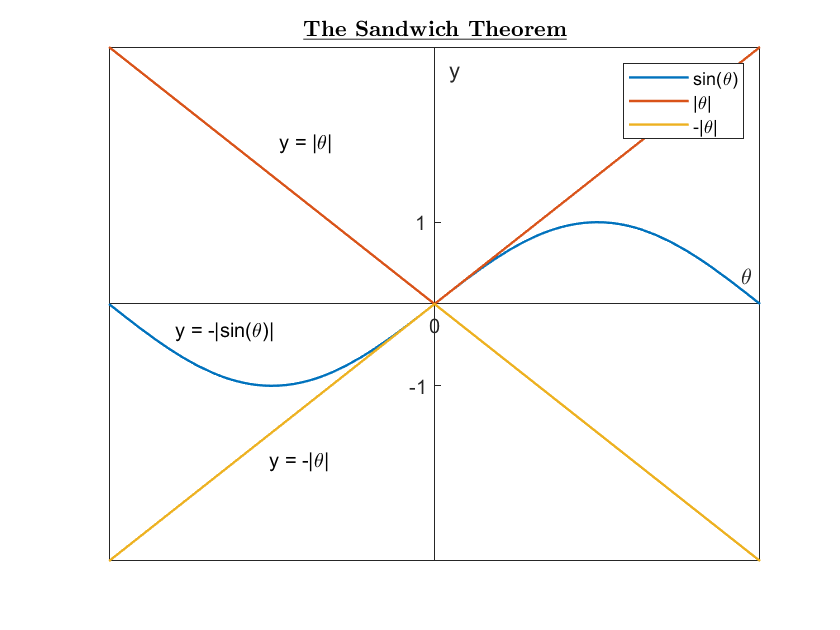

syms x
f(x) = piecewise(x ~= 1,(x^2-1)/(x-1));
% fplot(f(x),[0,3]);
subs(f(x), x, [0 1 2]);
f = x;
limit(f,x,3);
fplot(sin(x),[-pi pi],"LineWidth", 1.2 ), xticks([-pi, 0, pi]), xticklabels(["-\pi","0", "\pi"])
hold on
fplot(abs(x), [-pi, pi], "LineStyle","-","LineWidth",1.2), 
fplot(-abs(x), [-pi, pi], "LineWidth",1.2)
title("\underline{\textbf{The Sandwich Theorem}}","Interpreter","latex")
xlabel("\theta")
ylabel("y")
legend("sin(\theta)","|\theta|","-|\theta|")
yticks([-1 1]), yticklabels([-1 1])
text(-1.5,1.99,"y = |\theta|")
text(-2.5,-0.3,"y = -|sin(\theta)|")
text(-1.6,-1.9,"y = -|\theta|")
set(gca,'XAxisLocation','origin','YAxisLocation','origin')